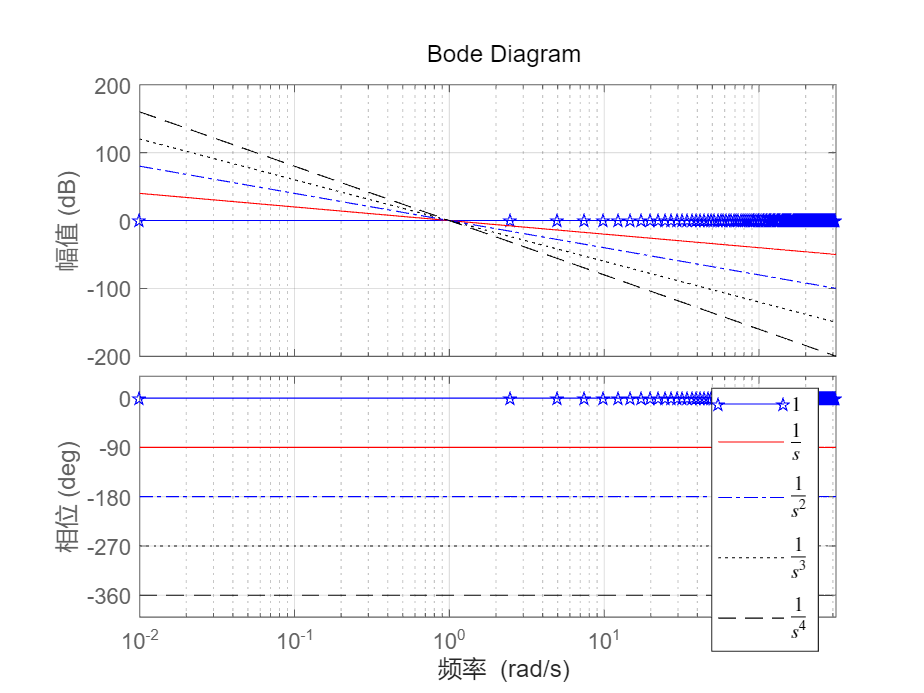

clear all;
close all;
clc;


s = tf('s');
P0=s^0;
P1=1/s;
P2=1/(s*s);
P3=1/(s^3);
P4=1/(s^4);
w = linspace(0.01,100*pi,128);

bode(P0,'p-',P1,'r-',P2,'b-.',P3,'black:',P4,'k--',w)
 
grid on; axis([min(w),max(w),-400,40])
hh = legend('$1$','$\frac{1}{s}$','$\frac{1}{s^2}$','$\frac{1}{s^3}$','$\frac{1}{s^4}$');
set(hh,'Interpreter','latex'); 

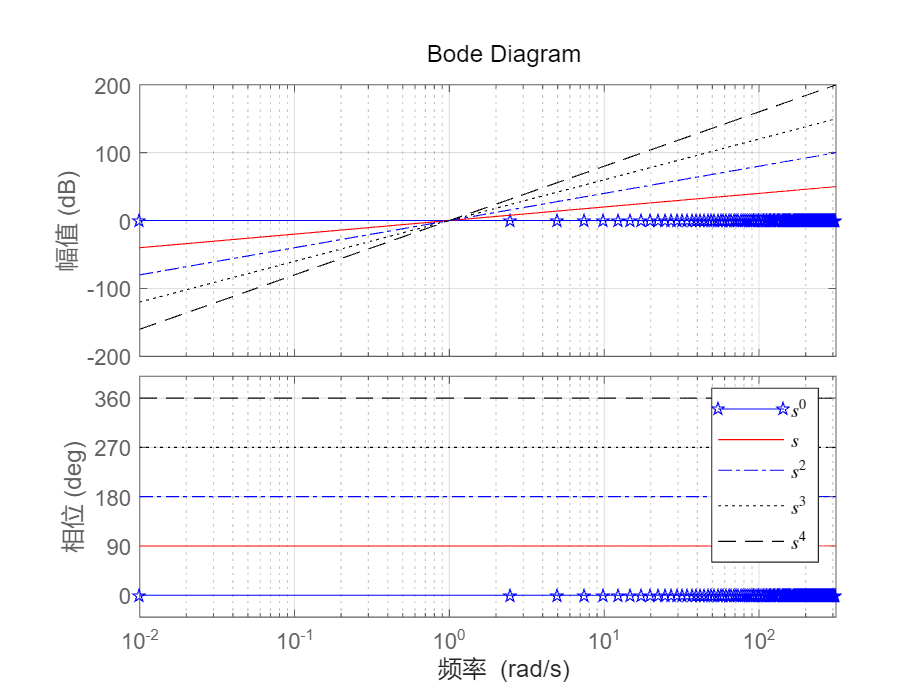

s = tf('s');
P0=s^0;
P1= s;
P2= (s*s);
P3= (s^3);
P4= (s^4);
w = linspace(0.01,100*pi,128);

bode(P0,'p-',P1,'r-',P2,'b-.',P3,'black:',P4,'k--',w)
 
grid on; axis([min(w),max(w), -40,400])
hh = legend('$s^0$','$ {s}$','${s^2}$','$ {s^3}$','$ {s^4}$');
set(hh,'Interpreter','latex'); 

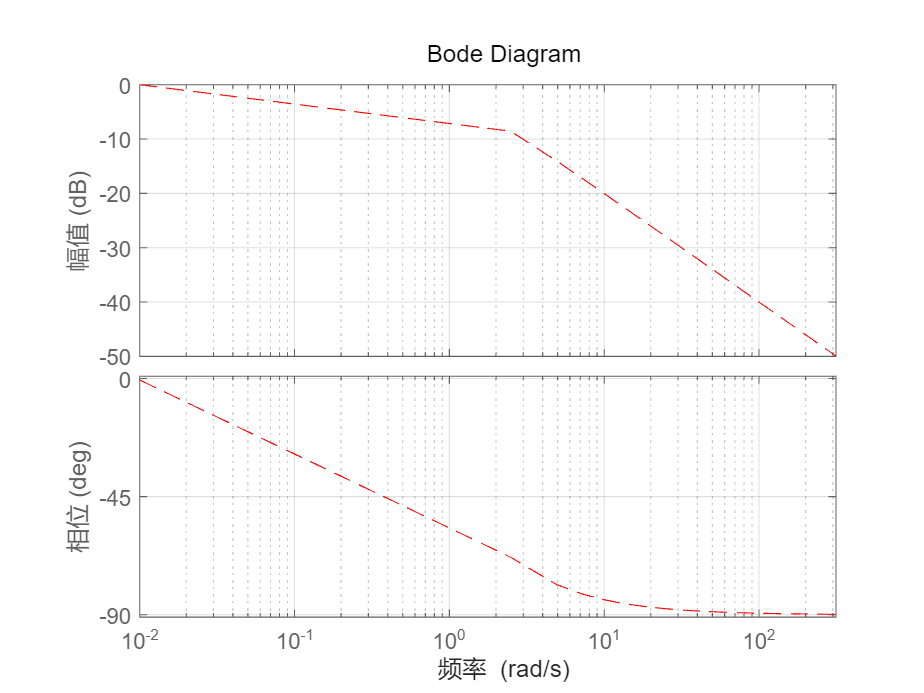

s = tf('s');
P0=1/(1+1*s);
w  = linspace(0.01,100*pi,128);
wl = logspace(0.01,1,100*pi);

figure; bode(P0, 'r--' ,w);  grid on;   

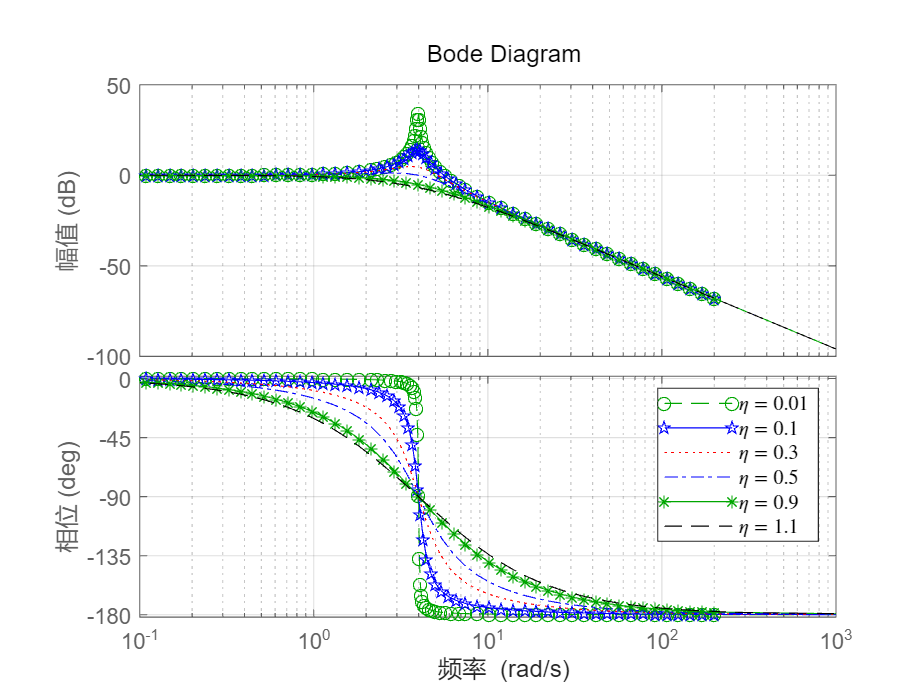



s = tf('s');

wn =4; eta=0.01;
P0 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);

wn =4; eta=0.1;
P1 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re1,im1,w1]=bode(P1);

wn =4; eta=0.3;
P2 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re2,im2,w2]=nyquist(P2);

wn =4; eta= 0.5;
P3 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re3,im3,w3]=nyquist(P3);

wn =4; eta= 0.9;
P4 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re4,im4,w4]=nyquist(P4);

wn =4; eta= 1.1;
P5 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re5,im5,w5]=nyquist(P5);

figure;
bode(P0,'g--o', ...
     P1,'p-', ...
     P2,'r:', ...
     P3,'b-.',...
     P4,'g-*',...
     P5,'black--');
grid on;
hh = legend('$\eta = 0.01$','$\eta = 0.1$','$\eta = 0.3$','$\eta = 0.5$','$\eta = 0.9$','$\eta = 1.1$');
set(hh,'Interpreter','latex');  

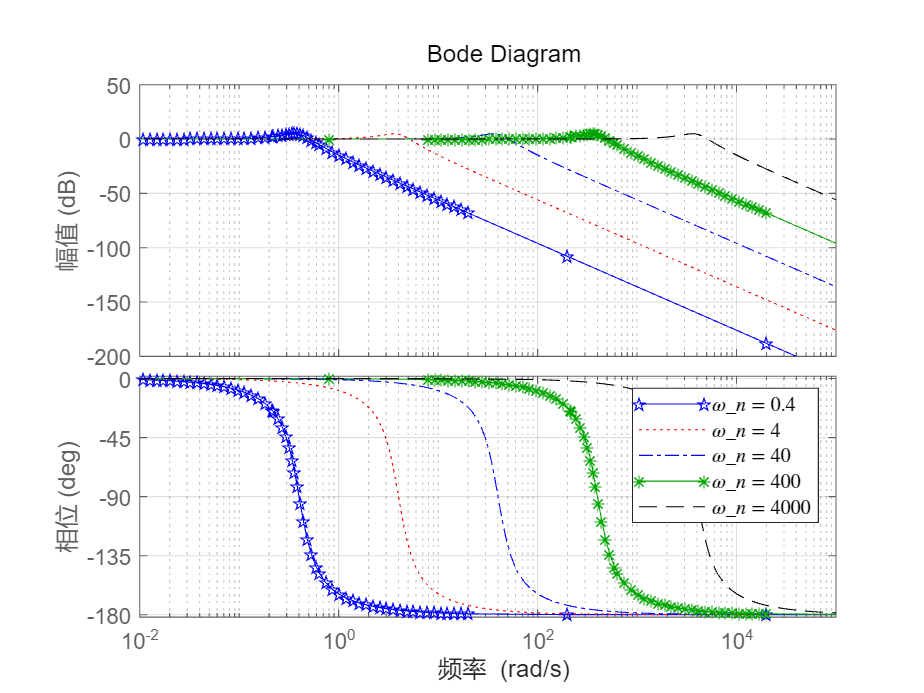

s = tf('s');

wn =0.4; eta=0.3;
P1 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re1,im1,w1]=bode(P1);

wn =4; eta=0.3;
P2 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re2,im2,w2]=nyquist(P2);

wn =40; eta= 0.3;
P3 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re3,im3,w3]=nyquist(P3);

wn =400; eta= 0.3;
P4 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re4,im4,w4]=nyquist(P4);

wn =4000; eta= 0.3;
P5 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
% [re5,im5,w5]=nyquist(P5);

figure;
bode(P1,'p-', ...
     P2,'r:', ...
     P3,'b-.',...
     P4,'g-*',...
     P5,'black--');
grid on;
hh = legend('$\omega_n = 0.4$','$\omega_n = 4$','$\omega_n = 40$','$\omega_n = 400$','$\omega_n = 4000$');
set(hh,'Interpreter','latex');  

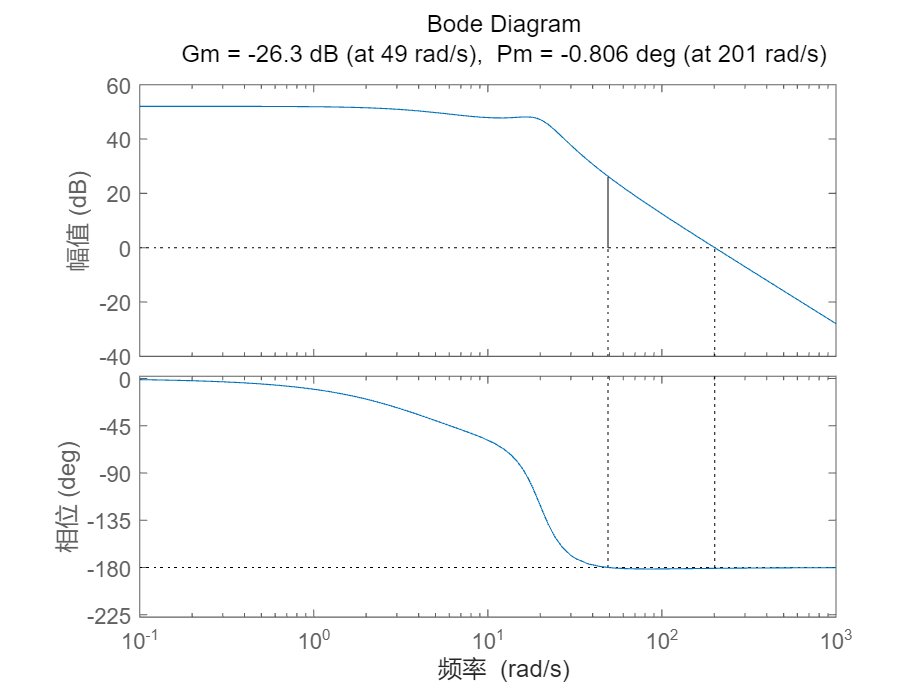

figure;
s = tf('s');
wn =20; eta= 0.3;
Pm = 100*wn*wn*(s+20)/((s+5)*(s*s+ 2*eta*s*wn+ wn*wn));

margin(Pm); 

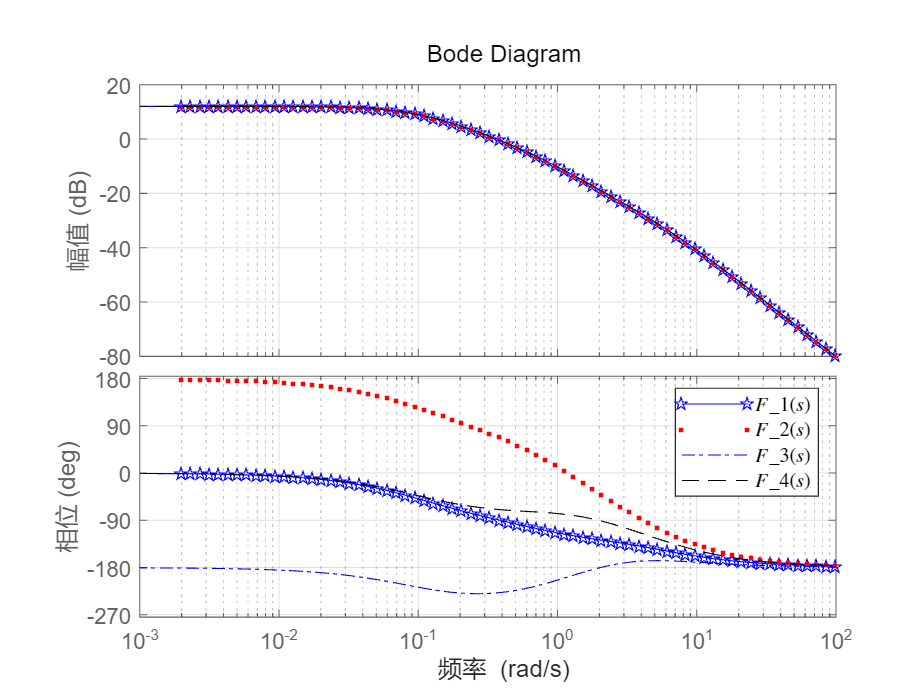

% hs=sgtitle('Phase and Magnitude Margins of $\cfrac{\omega_n^2}{s^2+2\eta \omega_n s+ \omega_n^2}$');
% set(hs,'Interpreter','latex');
s = tf('s');
F1 = (s+2)/((s+5)*(s+1)*(s+0.1));
F2 = (s-2)/((s+5)*(s+1)*(s+0.1));
F3 = (s+2)/((s+5)*(s-1)*(s+0.1));
F4 = (s-2)/((s+5)*(s-1)*(s+0.1));

figure;
bode(F1,'p-', ...
     F2,'r.', ...
     F3,'b-.',...
     F4,'black--');
grid on;
hh = legend('$F_{1}(s)$','$F_{2}(s)$','$F_{3}(s)$','$F_{4}(s)$');
set(hh,'Interpreter','latex');  

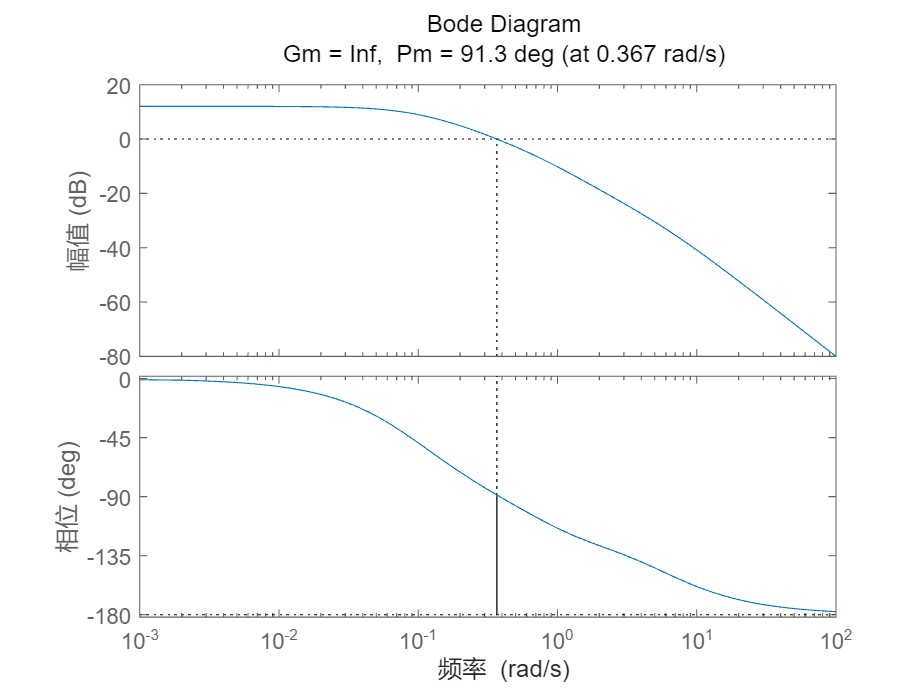

margin(F1)

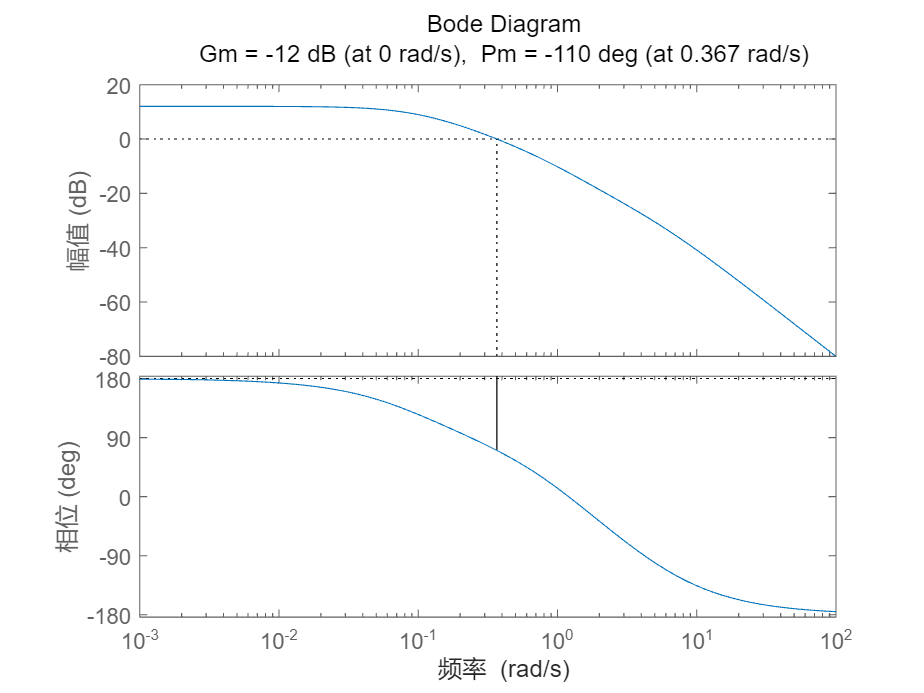

margin(F2)

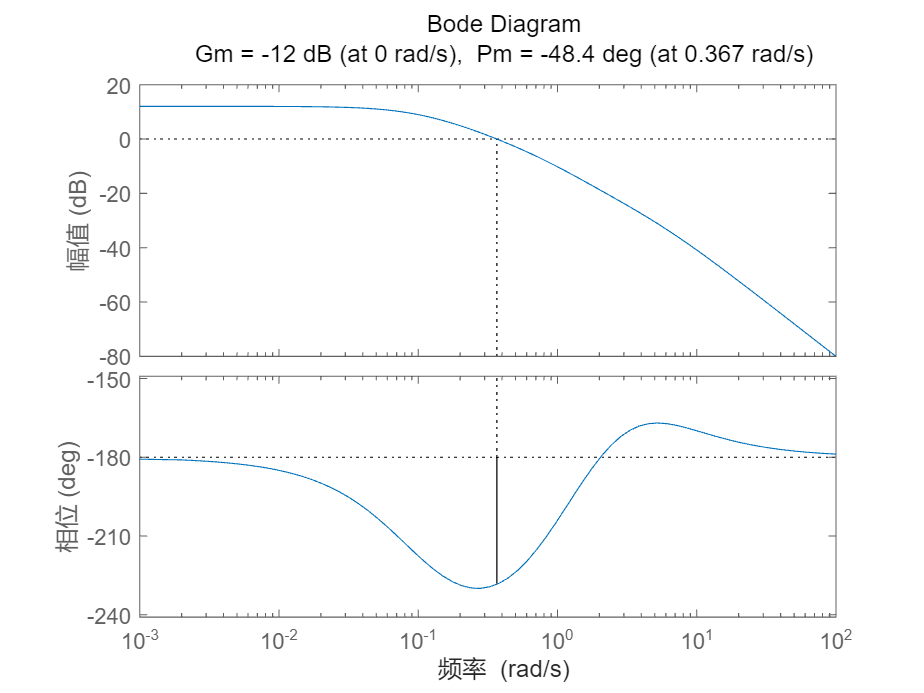

margin(F3)

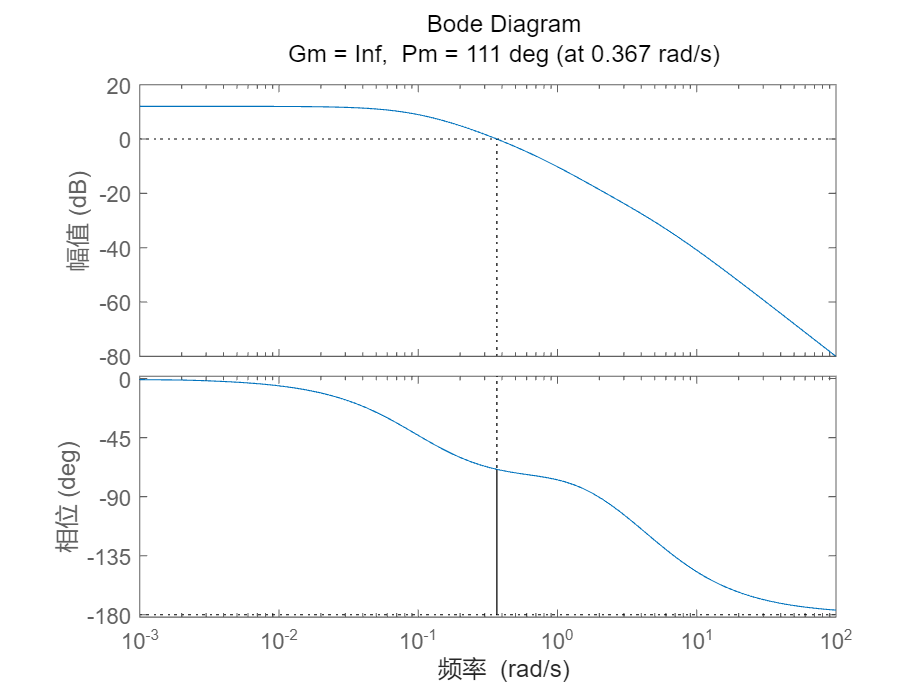

margin(F4)